# Proyecto Integrador III - Planificación dinámica con RRT*

Integrantes:  - William Andrade Gonzalez

                     - Glen Alejandro Guerrero Burbano

                     - Yeison Fernando Jimenez Agudelo

## GENERAR EL MAPA Y ENGROSAR OBSTACULOS

Se crea el mapa con los obstaculos

clear; clc; close all;

q_start = [5, 5];
q_goal  = [45, 35]; 

% 1. Generar el mapa inicial
addpath("auxiliar");
map = dibujarMapa(q_start, q_goal);
[rows, cols] = size(map); 

## Parametros simulación obstaculos y trayectorias emergentes

max_obstaculos_dinamicos = 1; % Límite de obstáculos que aparecerán
obs_generados = 0;
trayectoria_count = 1;
colores_rutas = lines(10); % Genera una paleta de 10 colores distintos

## Llamado función del planificador RRT*

% 2. Planificación Inicial
fprintf('--- PLANIFICACIÓN INICIAL ---\n');

--- PLANIFICACIÓN INICIAL ---


[path, found] = rrtStar(map, q_start, q_goal);

if ~found
    error('Fallo al encontrar la ruta inicial. Verifica las coordenadas.');
end

## Simulación movimiento robot y obstáculos aleatorios

Se ha generado una simulación donde se simula el movimiento del robot con la matriz PATH que representa las coordenadas x,y de los nodos que sigue la trayectoria del robot (Es una movimiento ideal); En la práctica este movimiento deberá ser implementado con los algoritmos de lectura de sensores o odometría e incluso al control del robot. Por ahora se lo hace de una manera ideal desde simulación para enfocarse más en la planificación.

% Dibujar ruta inicial y enumerarla
plot(path(:,1), path(:,2), 'Color', colores_rutas(trayectoria_count,:), 'LineWidth', 2);
text(path(1,1) + 1, path(1,2) + 2, sprintf('Ruta %d', trayectoria_count), ...
    'Color', colores_rutas(trayectoria_count,:), 'FontWeight', 'bold', 'FontSize', 10);
h_robot = plot(path(1,1), path(1,2), 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k');

% 3. Simulación de Movimiento y Replanificación
idx = 1;

% El obstáculo aparecerá aleatoriamente entre el paso 3 y 5 de la ruta actual
paso_aparicion_obs = randi([3, 5]); 

fprintf('\n--- INICIANDO MOVIMIENTO ---\n');


--- INICIANDO MOVIMIENTO ---


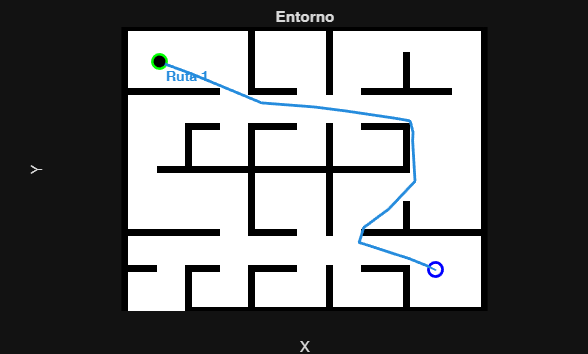


ALERTA: Obstáculo # 1 detectado.


Ruta 1 bloqueada. 
 Planificando nueva ruta...


>>> Ruta 2 encontrada.


while idx <= size(path, 1)
    % Actualizar posición del robot
    current_pos = path(idx, :);
    set(h_robot, 'XData', current_pos(1), 'YData', current_pos(2));
    drawnow;
    pause(0.2); 
    
    % --- APARICIÓN ALEATORIA DE OBSTÁCULO CERCA DEL INICIO ---
    if idx == paso_aparicion_obs && obs_generados < max_obstaculos_dinamicos
        fprintf('\nALERTA: Obstáculo # %d detectado.\n', obs_generados + 1);
        
        % Colocar obstáculo un par de nodos adelante en su trayectoria actual
        obs_idx = min(idx + 2, size(path,1));
        obs_x = round(path(obs_idx, 1));
        obs_y = round(path(obs_idx, 2));
        
        % Límites del nuevo bloque de obstáculo
        r_min = max(1, obs_y-3); r_max = min(rows, obs_y+3);
        c_min = max(1, obs_x-3); c_max = min(cols, obs_x+3);
        
        % Insertar obstáculo en el mapa y dibujarlo
        map(r_min:r_max, c_min:c_max) = 1;
        patch([c_min c_max c_max c_min], [r_min r_min r_max r_max], ...
              [1 0.2 0.2], 'EdgeColor', 'k', 'FaceAlpha', 0.9);
        drawnow;
        
        obs_generados = obs_generados + 1;
        
        % --- DETECCIÓN DE INVALIDEZ ---
        ruta_invalida = false;
        for j = idx:(size(path,1)-1)
            if isCollision(path(j,:), path(j+1,:), map)
                ruta_invalida = true;
                break;
            end
        end
        
        if ruta_invalida
            fprintf('Ruta %d bloqueada. \n Planificando nueva ruta...\n', trayectoria_count);
            plot(current_pos(1), current_pos(2), 'x', 'Color', colores_rutas(trayectoria_count,:), 'MarkerSize', 10, 'LineWidth', 2); 
            
            % --- REPLANIFICAR ---
            [new_path, found_new] = rrtStar(map, current_pos, q_goal);
            
            if found_new
                trayectoria_count = trayectoria_count + 1;
                fprintf('>>> Ruta %d encontrada.\n', trayectoria_count);
                
                % DIBUJAR NUEVA RUTA SIN BORRAR LA ANTERIOR
                plot(new_path(:,1), new_path(:,2), '-', 'Color', colores_rutas(trayectoria_count,:), 'LineWidth', 2);
                
                % Colocar texto de enumeración en el nuevo punto de inicio
                text_x = new_path(1,1) + 1;
                text_y = new_path(1,2) - 2;
                text(text_x, text_y, sprintf('Ruta %d', trayectoria_count), ...
                    'Color', colores_rutas(trayectoria_count,:), 'FontWeight', 'bold', 'FontSize', 10);
                
                % Actualizar variables para seguir la nueva ruta
                path = new_path;
                idx = 1; % Reiniciamos el índice 
                % Programar aparición del próximo obstáculo en la nueva ruta
                paso_aparicion_obs = randi([3, 5]); 
            else
                fprintf('Imposible encontrar nueva ruta. El robot se detiene.\n');
                break;
            end
        end
    end
    idx = idx + 1;
end

fprintf('\n--- SIMULACIÓN FINALIZADA ---\n');


--- SIMULACIÓN FINALIZADA ---


fprintf('Se planearon un total de %d rutas.\n', trayectoria_count);

Se planearon un total de 2 rutas.


## RRT* Planificación basada en muestreo (Rapidly-exploring Random Tree Star).

function [final_path, path_found] = rrtStar(map, q_start, q_goal)
    max_iter = 2500;     %2500    
    step_size = 3;       %5  
    goal_threshold = 3;  %3   
    rewire_radius = 8;  %12    
    
    [rows, cols] = size(map);
    nodes.coord = zeros(max_iter, 2);
    nodes.parent = zeros(max_iter, 1);
    nodes.cost = zeros(max_iter, 1);
    
    nodes.coord(1, :) = q_start;
    nodes.parent(1) = 0;
    nodes.cost(1) = 0;
    node_count = 1;
    
    for i = 1:max_iter
        if rand < 0.1 
            q_rand = q_goal;
        else
            q_rand = [rand * cols, rand * rows];
        end
        
        dists = sum((nodes.coord(1:node_count, :) - q_rand).^2, 2);
        [~, nearest_idx] = min(dists);
        q_near = nodes.coord(nearest_idx, :);
        
        diff = q_rand - q_near;
        dist_val = norm(diff);
        if dist_val > step_size
            q_new = q_near + (diff / dist_val) * step_size;
        else
            q_new = q_rand;
        end
        
        if q_new(1) < 1 || q_new(1) > cols || q_new(2) < 1 || q_new(2) > rows
            continue;
        end
        
        if ~isCollision(q_near, q_new, map)
            dists_all = sqrt(sum((nodes.coord(1:node_count, :) - q_new).^2, 2));
            neighbor_indices = find(dists_all <= rewire_radius);
            
            min_cost = nodes.cost(nearest_idx) + dist(nodes.coord(nearest_idx,:), q_new);
            best_parent_idx = nearest_idx;
            
            for j = 1:length(neighbor_indices)
                neighbor_idx = neighbor_indices(j);
                tentative_cost = nodes.cost(neighbor_idx) + dist(nodes.coord(neighbor_idx,:), q_new);
                
                if tentative_cost < min_cost && ~isCollision(nodes.coord(neighbor_idx,:), q_new, map)
                    min_cost = tentative_cost;
                    best_parent_idx = neighbor_idx;
                end
            end
            
            node_count = node_count + 1;
            nodes.coord(node_count, :) = q_new;
            nodes.parent(node_count) = best_parent_idx;
            nodes.cost(node_count) = min_cost;
            
            for j = 1:length(neighbor_indices)
                neighbor_idx = neighbor_indices(j);
                new_cost_via_qnew = nodes.cost(node_count) + dist(q_new, nodes.coord(neighbor_idx,:));
                
                if new_cost_via_qnew < nodes.cost(neighbor_idx)
                    if ~isCollision(q_new, nodes.coord(neighbor_idx,:), map)
                        nodes.parent(neighbor_idx) = node_count;
                        nodes.cost(neighbor_idx) = new_cost_via_qnew;
                    end
                end
            end
        end
    end
    
    dists_to_goal = sqrt(sum((nodes.coord(1:node_count, :) - q_goal).^2, 2));
    [min_dist_goal, goal_node_idx] = min(dists_to_goal);
    
    path_found = false;
    final_path = [];
    if min_dist_goal <= goal_threshold
        if ~isCollision(nodes.coord(goal_node_idx, :), q_goal, map)
            path_found = true;
            final_path = q_goal;
            curr_idx = goal_node_idx;
            while curr_idx ~= 0
                final_path = [nodes.coord(curr_idx, :); final_path];
                curr_idx = nodes.parent(curr_idx);
            end
        end
    end
end

function d = dist(q1, q2)
    d = norm(q1 - q2);
end

## Función auxiliar

function collision = isCollision(q1, q2, map)

%Aumenta el ultimo multiplicador para revisar colisiones con más detalle
    samples = max(2, ceil(norm(q1 - q2) * 2));  
    x_vals = linspace(q1(1), q2(1), samples);
    y_vals = linspace(q1(2), q2(2), samples);
    
    [rows, cols] = size(map);
    collision = false;
    
    for k = 1:samples
        c = round(x_vals(k));
        r = round(y_vals(k)); 
        c = max(1, min(c, cols));
        r = max(1, min(r, rows));
        
        if map(r, c) == 1 
            collision = true;
            return;
        end
    end
end